%% dilution_set_points.m
%
% Author:   Lincoln Scheer
% Date:     1 April 2024
%
% This script file is for calculating MFC set points to dilute two known
% gasses delivered at discrete set points.

clc, clear, close all

Dilution Assumptions

% Dilution Assumptions

ct_low_ppm = 5000;   % Target Low [ppm]
ct_high_ppm = 5000;  % Target High [ppm]
resolution = 10;   % No. Dilution Tests
ca_ppm = 1000000;       % Tank A Concentration [ppm]
cb_ppm = 399.8;       % Tank B Concentration [ppm]
qa_lpm = 0.05;       % MFC Tank A [lpm]
qb_lpm = 0.2;       % MFC Tank B [lpm]

% Environment Assumptions
P = 101325;            % Atmospheric Pressure [Pa]
T = 293.15;            % Atmostpheric Temp. [K]

% Unit Conversion Anonymous Functions

ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;
lpm_to_cms = @(lpm) lpm/60000;
cms_to_lpm = @(cms) cms*60000;

% Convert To SI Units

% ppm --> mol/m^3
ct_low = ppm_to_mol(ct_low_ppm);
ct_high = ppm_to_mol(ct_high_ppm);
ca = ppm_to_mol(ca_ppm);
cb = ppm_to_mol(cb_ppm);

% lpm --> cms
qa = lpm_to_cms(qa_lpm);
qb = lpm_to_cms(qb_lpm);

% Governing Equation

ct_eqn = @(ca, cb, qa, qb) (qa.*ca+qb.*cb)./(qa+qb);

% Preprocessing

ct_rng = linspace(ct_low, ct_high, resolution);

qa_min = qa*0.1;
qa_max = qa-qa*0.1;

qb_min = qb*0.1;
qb_max = qb-qb*0.1;

qa_rng = linspace(qa_min, qa_max, resolution);
qb_rng = linspace(qb_min, qb_max, resolution);

[qa_mesh, qb_mesh] = meshgrid(qa_rng, qb_rng);
ct_calc = ct_eqn(ca, cb, qa_mesh, qb_mesh);

qa_mesh_lpm = cms_to_lpm(qa_mesh);
qb_mesh_lpm = cms_to_lpm(qb_mesh);
ct_calc_ppm = mol_to_ppm(ct_calc);

target_ct_rng = logspace(log10(ct_low_ppm),log10(ct_high_ppm), resolution);
target_qa_rng = zeros(1,resolution);
target_qb_rng = zeros(1,resolution);
target_ct_rng_calc = zeros(1,resolution);
for i = 1:resolution

    diff = abs(ct_calc_ppm - target_ct_rng(i));

    [row, col, val] = find(diff <= min(min(diff)));
    row = row(1);
    col = col(1);
    tgt = ct_calc_ppm(row, col);
    
    target_ct_rng_calc(i) = tgt(1);
    target_qa_rng(i) = qa_mesh_lpm(row, col);
    target_qb_rng(i) = qb_mesh_lpm(row, col);

end



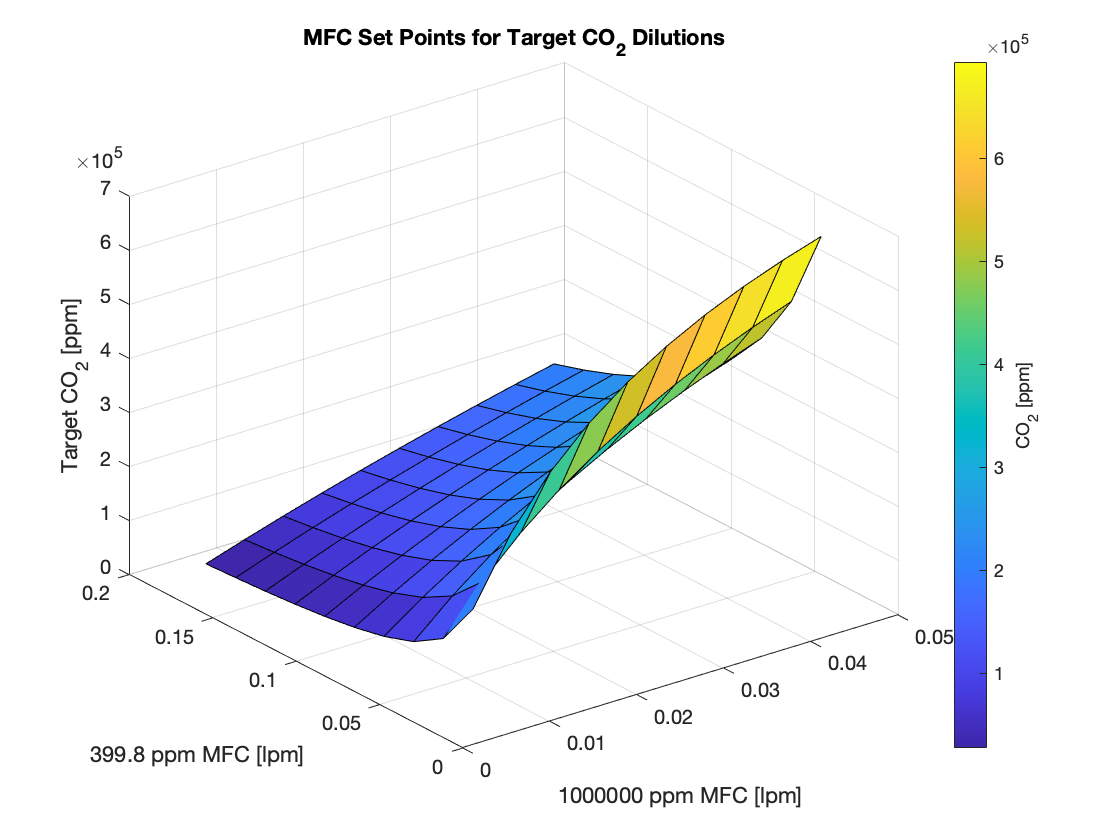

% Surface Plots

surf(qa_mesh_lpm, qb_mesh_lpm, ct_calc_ppm);
a = colorbar;
a.Label.String = 'CO_2 [ppm]';

xlabel("" + ca_ppm + " ppm MFC [lpm]");
ylabel("" + cb_ppm + " ppm MFC [lpm]");
zlabel('Target CO_2 [ppm]');
title("MFC Set Points for Target CO_2 Dilutions");

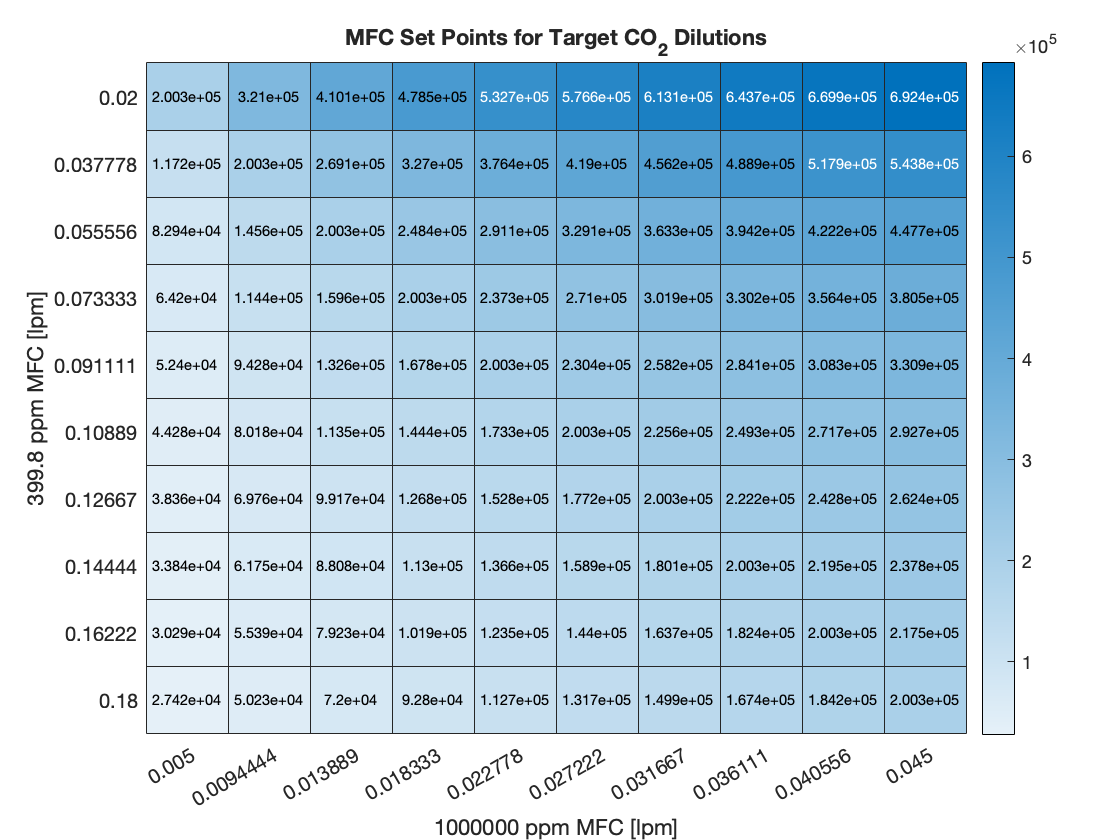

% Heatmap Plots

heatmap(cms_to_lpm(qa_rng), cms_to_lpm(qb_rng), ct_calc_ppm);
title("MFC Set Points for Target CO_2 Dilutions");
xlabel("" + ca_ppm + " ppm MFC [lpm]");
ylabel("" + cb_ppm + " ppm MFC [lpm]");

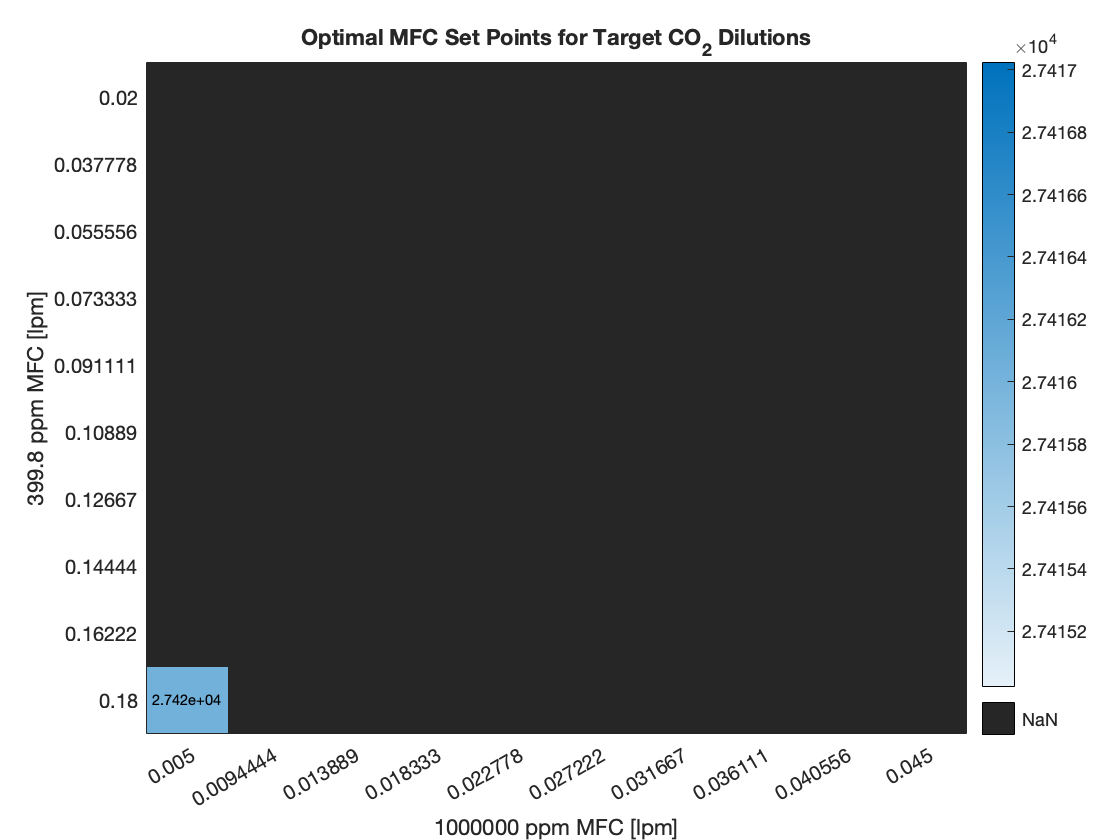


ct_calc_ppm_masked = ct_calc_ppm;
ct_calc_ppm_masked(~ismember(ct_calc_ppm, target_ct_rng_calc)) = NaN;

heatmap(cms_to_lpm(qa_rng), cms_to_lpm(qb_rng), ct_calc_ppm_masked);
title("Optimal MFC Set Points for Target CO_2 Dilutions");
xlabel("" + ca_ppm + " ppm MFC [lpm]");
ylabel("" + cb_ppm + " ppm MFC [lpm]");

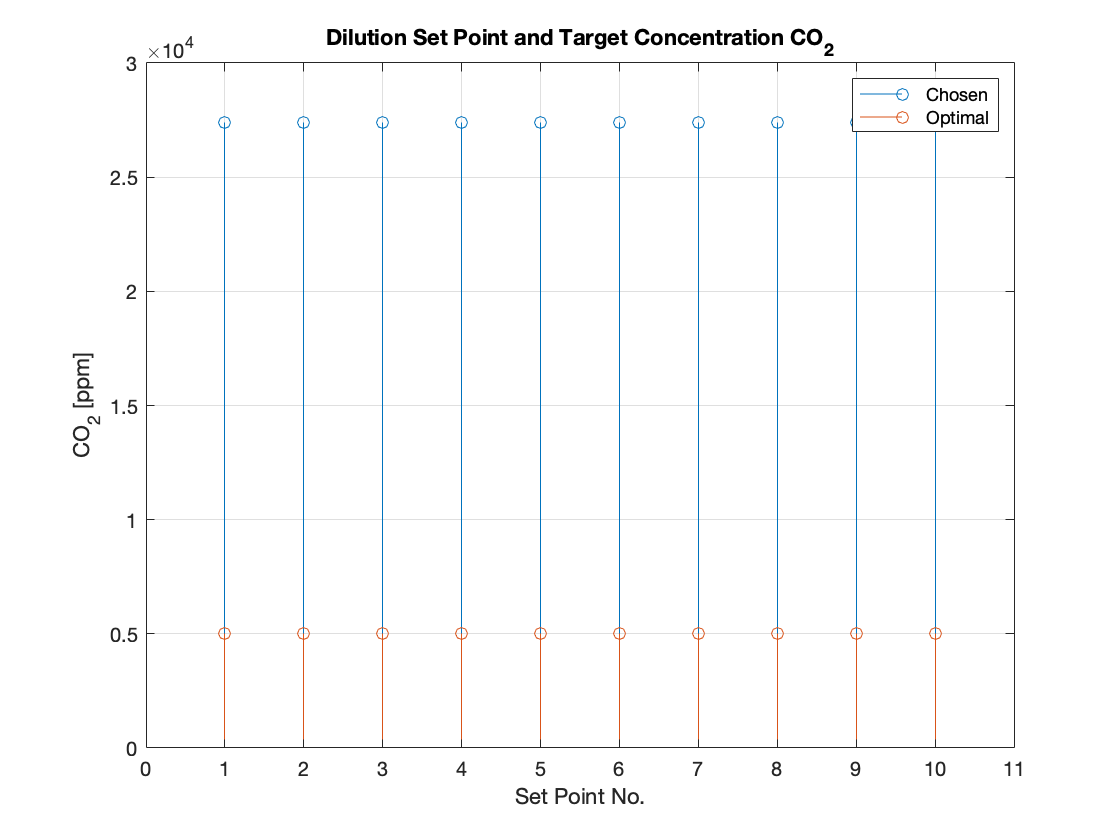


stem(1:resolution, target_ct_rng_calc)
hold on
stem(1:resolution, target_ct_rng)
legend(["Chosen", "Optimal"])
xlabel("Set Point No.");
ylabel("CO_2 [ppm]");
title("Dilution Set Point and Target Concentration CO_2");
grid on
xlim([0, resolution+1])

labels = ["Target [ppm]", "MFC " + ca_ppm + " ppm [lpm]", "MFC " + cb_ppm + " ppm [lpm]"];
dilution_results = array2table([target_ct_rng_calc', target_qa_rng', target_qb_rng'], "VariableNames", labels)

dilution_results = 10×3 table
    Target [ppm]    MFC 1000000 ppm [lpm]    MFC 399.8 ppm [lpm]
    ____________    _____________________    ___________________

       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
       27416                0.005                   0.18        
